%% MAIN: FxLMS vs Moving Jackhammer (Full Digital Twin)
% Architettura: Feed-forward FxLMS con Secondary Path Compensation

clearvars -except s_est s_real_coeffs Fs; 
clc; % Pulisce solo il terminale

%% 1. Configurazione e Caricamento Stima
% Assicurati di aver fatto girare lo script di Identificazione prima!
% Se s_est non è in memoria, lo rigeneriamo al volo per sicurezza.
if exist('ANC_Calibration.mat', 'file')
    load('ANC_Calibration.mat');
    disp('Dati di calibrazione caricati correttamente.');
else
    error('File di calibrazione non trovato! Esegui prima lo script ID.');
end

Dati di calibrazione caricati correttamente.



Fs = 48000;
T = 10; 
N_samples = T * Fs;
t = (0:N_samples-1)' / Fs;

%% 2. Generazione Scenari (Moving Source)
disp('Generazione rumore complesso in movimento...');

Generazione rumore complesso in movimento...


gen = AdvancedSoundGenerator();

opts.startPos = [2, 3]; % Parte a 6 metri di lato
opts.endPos   = [3.5, 3]; % Finisce vicinissimo al microfono
opts.bpm = 480;

[x, d, ~] = gen.MovingJackhammer(T, Fs, opts);

% Allineamento campioni
L = min([length(x), length(d), N_samples]);
x = x(1:L); d = d(1:L); t = t(1:L);

%% 3. Inizializzazione FxLMS Filter
disp('Inizializzazione Controller FxLMS...');

Inizializzazione Controller FxLMS...



Lw = 1024;        % Filtro di controllo lungo per gestire distanze elevate
mu_fx = 0.0008;    % Molto più basso per evitare i picchi
eps_fx = 0.1;      % Più robusto\

% Creazione oggetto dalla tua classe
anc_controller = FxLMSFilter(Lw, s_est, mu_fx, eps_fx);

%% 4. Simulazione Real-Time (Fisica + DSP)
disp('Avvio ANC Online...');

Avvio ANC Online...



y_dsp = zeros(L, 1);    % Segnale elettrico calcolato dal chip
y_phys = zeros(L, 1);   % Segnale acustico emesso dalla cassa (Filtrato da S)
e = zeros(L, 1);        % Errore residuo al microfono
s_state = zeros(length(s_est)-1, 1); % Stato interno della cassa fisica

tic;
for n = 1:L
    % 1. Il DSP calcola l'anti-rumore y basandosi su x e l'errore precedente
    % Usiamo e(max(1,n-1)) perché il DSP legge l'errore del campione precedente
    [y_dsp(n), ~] = anc_controller.step(x(n), e(max(1,n-1)));
    
    % 2. LA FISICA: L'anti-rumore passa per la cassa reale S(z)
    % Usiamo gli stessi coefficienti 's_real_coeffs' dello script ID
    [y_phys(n), s_state] = filter(s_real_coeffs, 1, y_dsp(n), s_state);
    
    % 3. CANCELLAZIONE ACUSTICA: Il rumore d incontra l'anti-rumore fisico y_phys
    e(n) = d(n) - y_phys(n);
end
t_sim = toc;

fprintf('Simulazione completata in %.2f s.\n', t_sim);

Simulazione completata in 5.36 s.


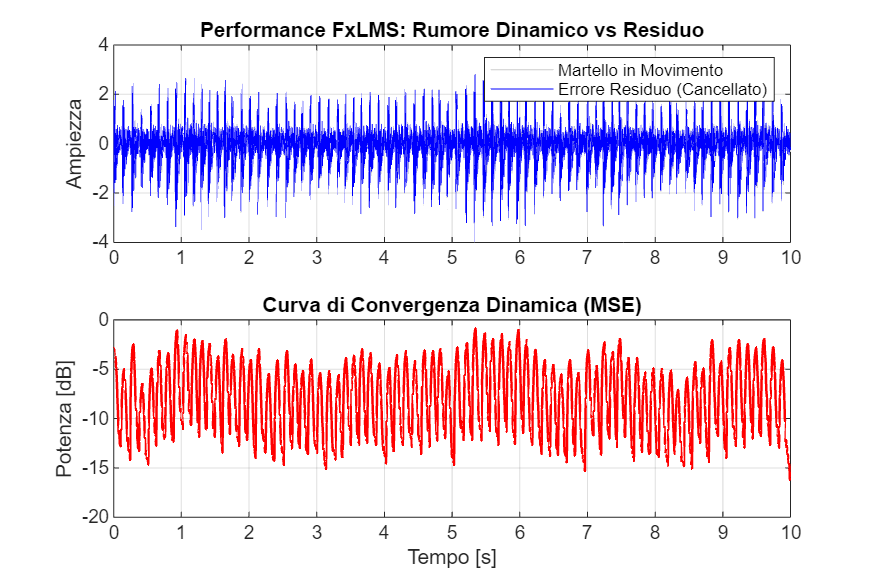


%% 5. Analisi Risultati
window = round(Fs * 0.05);
mse_dB = 10 * log10(movmean(e.^2, window) + 1e-12);

figure('Name', 'FxLMS Performance Dashboard', 'Position', [100 100 1200 800], 'Color', 'w');

subplot(2,1,1);
plot(t, d, 'Color', [0.8 0.8 0.8]); hold on;
plot(t, e, 'b');
title('Performance FxLMS: Rumore Dinamico vs Residuo');
legend('Martello in Movimento', 'Errore Residuo (Cancellato)');
grid on; ylabel('Ampiezza');

subplot(2,1,2);
plot(t, mse_dB, 'r', 'LineWidth', 1.2);
title('Curva di Convergenza Dinamica (MSE)');
xlabel('Tempo [s]'); ylabel('Potenza [dB]');
grid on;


% Metrica finale
att_db = 10*log10(mean(d(end-Fs:end).^2)) - 10*log10(mean(e(end-Fs:end).^2));
fprintf('Attenuazione Finale Media: %.2f dB\n', att_db);

Attenuazione Finale Media: 0.09 dB



%% 6. Test Audio
%%disp('Ascolto: Risultato FxLMS (Sentirai il tracking adattivo)...');
%%soundsc(e, Fs);